clc
close all
clearvars

file_group = "wt";
exp_num = "exp51";

calib_dir = strcat("calib_",exp_num);
data_dir = fullfile(pwd,"mgat1ko_data");

%----- Adjusted R2 and L2 measures -----%
r2l2_wt = readtable(fullfile(calib_dir,"r2l2_measures_wt.csv"));
r2l2_ko = readtable(fullfile(calib_dir,"r2l2_measures_mgat1ko.csv"));

r2 = r2l2_wt.mean_R2;
fprintf("WT: %f +- %f",mean(r2),std(r2)/sqrt(length(r2)));

WT: 0.962372 +- 0.005140

fprintf("Min/Median/Max: %f \t %f \t %f",min(r2),median(r2),max(r2))

Min/Median/Max: 0.851922 	 0.972678 	 0.989622

r2 = r2l2_ko.mean_R2;
fprintf("MGAT1KO: %f +- %f",mean(r2),std(r2)/sqrt(length(r2)))

MGAT1KO: 0.893831 +- 0.007652

fprintf("Min/Median/Max: %f \t %f \t %f",min(r2),median(r2),max(r2))

Min/Median/Max: 0.773667 	 0.904144 	 0.965556

r2l2 = readtable(fullfile(calib_dir,strcat("r2l2_measures_",file_group,".csv")));
i1 = 2;
i2 = 3;

%----- Model structure -----%
current_names = {'iktof', 'ikslow1', 'ikslow2', 'ikss'};
tune_idx = cell(5,1); % iktof, iktos, ikslow1, ikslow2, ikss
tune_idx{1} = [1, 2, 3, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10, 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];

[mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx);

pdefault = cell(5,1);
pdefault{1} = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, ...
    0.000152, 0.067083, 0.00095, 0.051335, 0.3846];
pdefault{2} = [-1050, 270, 0.0629];
pdefault{3} = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18, 2.058, 803.0, 0.16];
pdefault{4} = [4912, 5334, 0.16];
pdefault{5} = [0.0862, 1235.5, 13.17, 0.0611];

%----- Protocol & Experimental data -----%
matching_table = readtable(...
    fullfile(data_dir,strcat("matching-table-",file_group,".xlsx")));
file_names = matching_table.trace_file_name_4half;
file_names(cellfun(@isempty,file_names)) = [];
file_names = string(file_names);
num_files = length(file_names);

hold_volt = -70;
volts = -30:10:50;
ideal_hold_time = 120;
ideal_end_time = 4.6*1000;
ek = -91.1;

protocol = cell(6,1);
protocol{1} = hold_volt;
protocol{2} = ek;
protocol{3} = volts;

File 1: 15o26002.xlsx / Mean R-squared: 0.869822 / Mean L2: 0.827533 


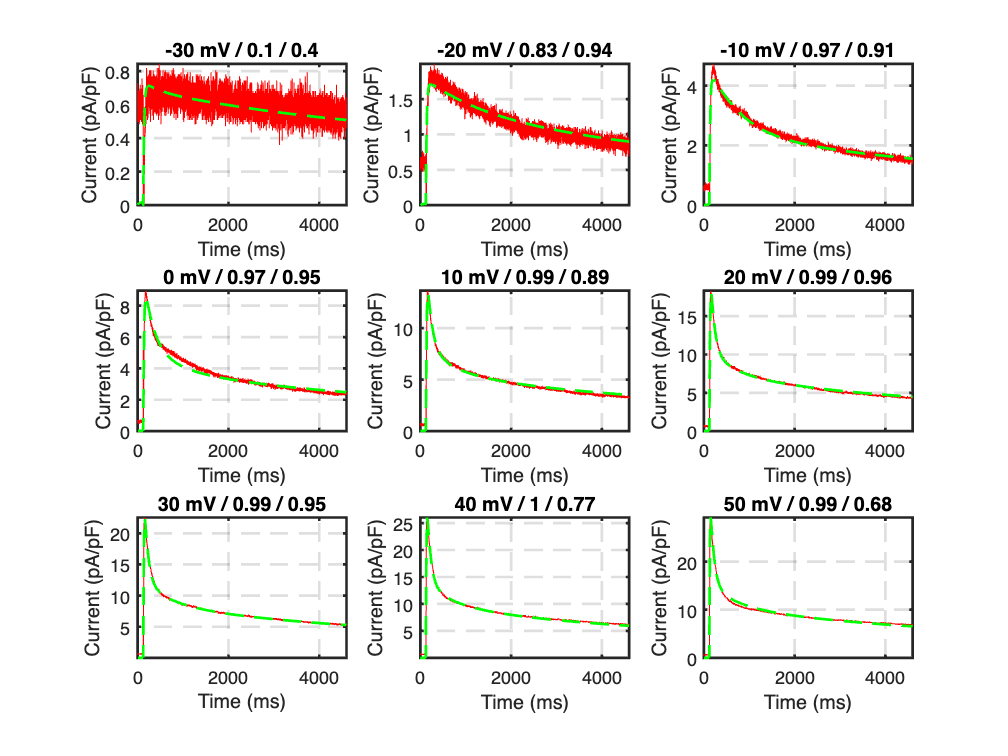

File 2: 15o26005.xlsx / Mean R-squared: 0.934522 / Mean L2: 0.735600 


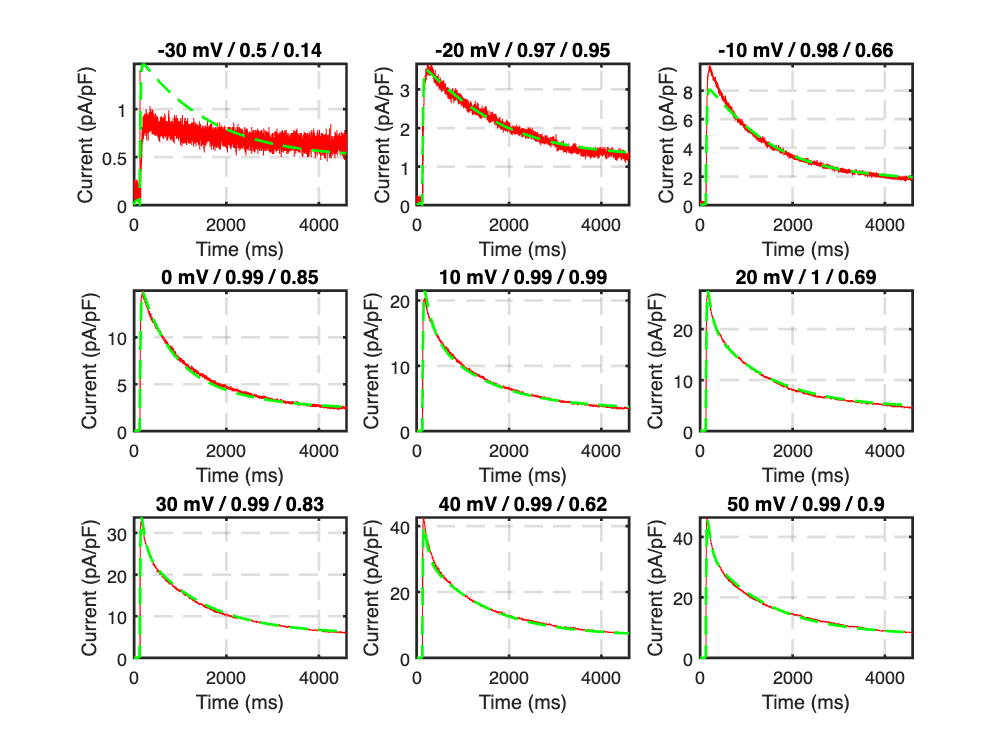

File 3: 15o26008.xlsx / Mean R-squared: 0.975167 / Mean L2: 0.743978 


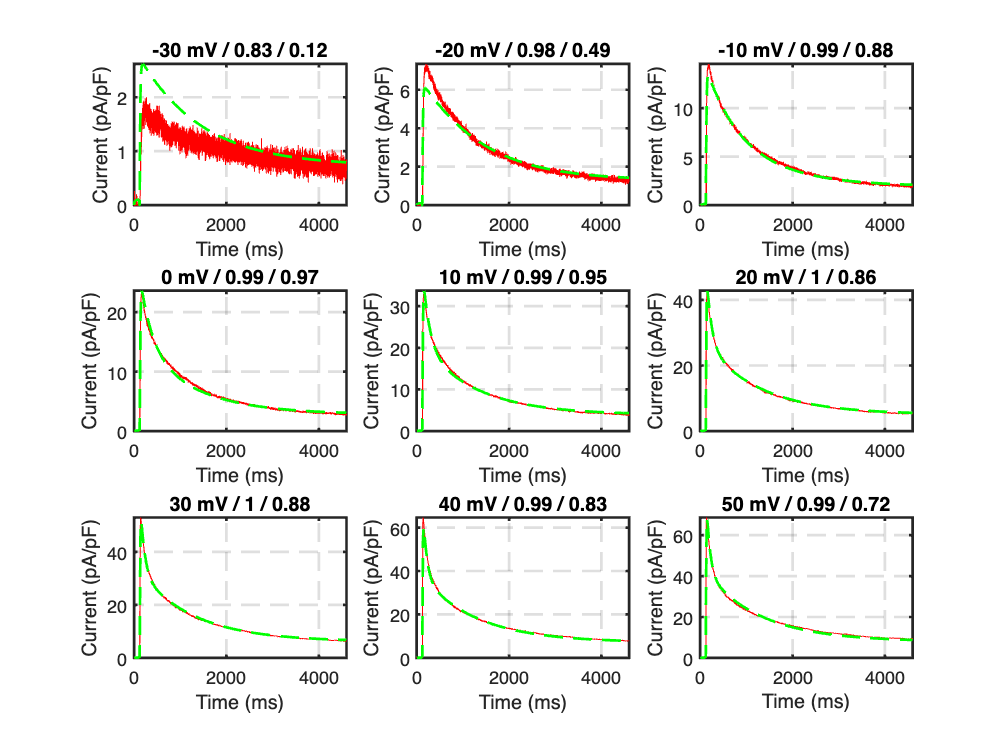

File 4: 15o26014.xlsx / Mean R-squared: 0.974711 / Mean L2: 0.711022 


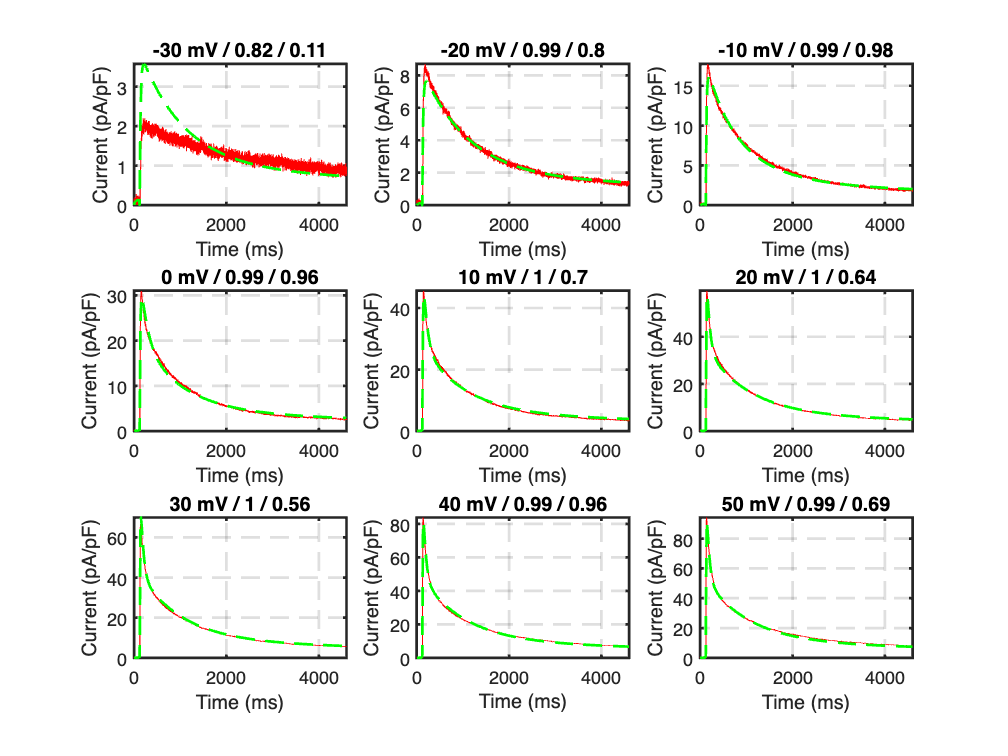

File 5: 15o26017.xlsx / Mean R-squared: 0.952178 / Mean L2: 0.746522 


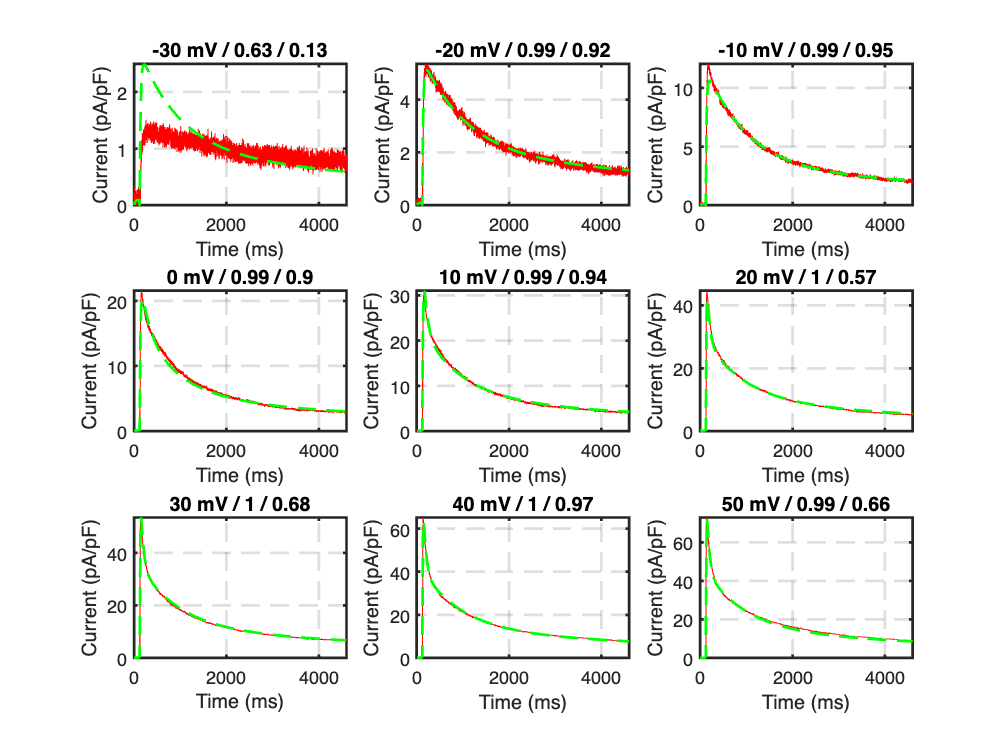

File 6: 15o26020.xlsx / Mean R-squared: 0.982333 / Mean L2: 0.759511 


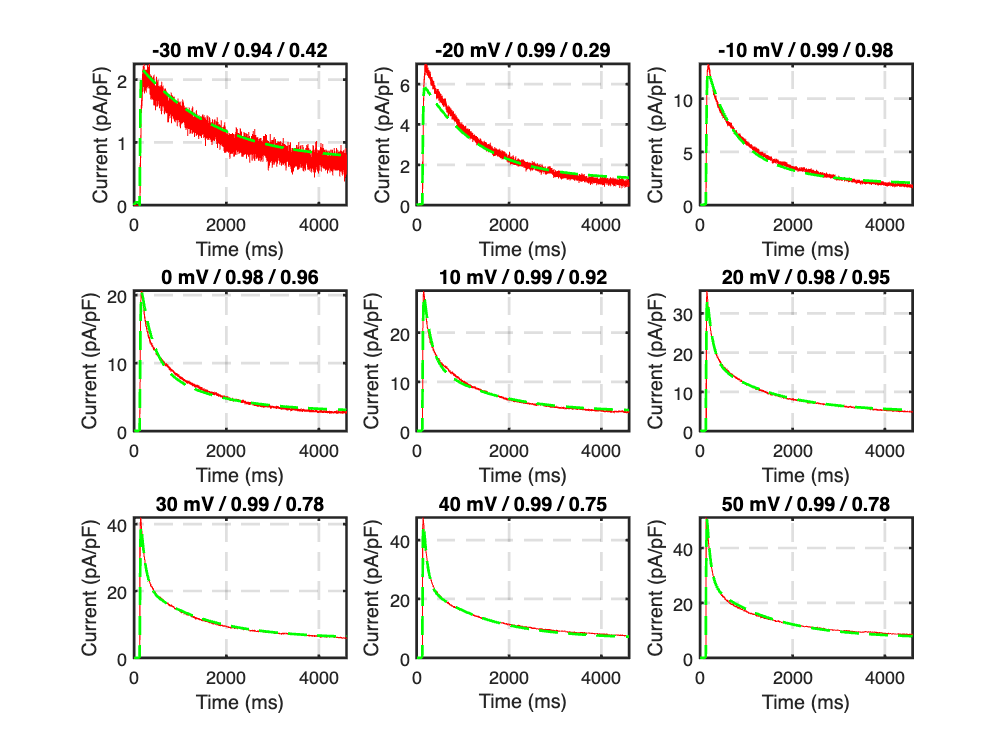

File 7: 15o26023.xlsx / Mean R-squared: 0.989622 / Mean L2: 0.874156 


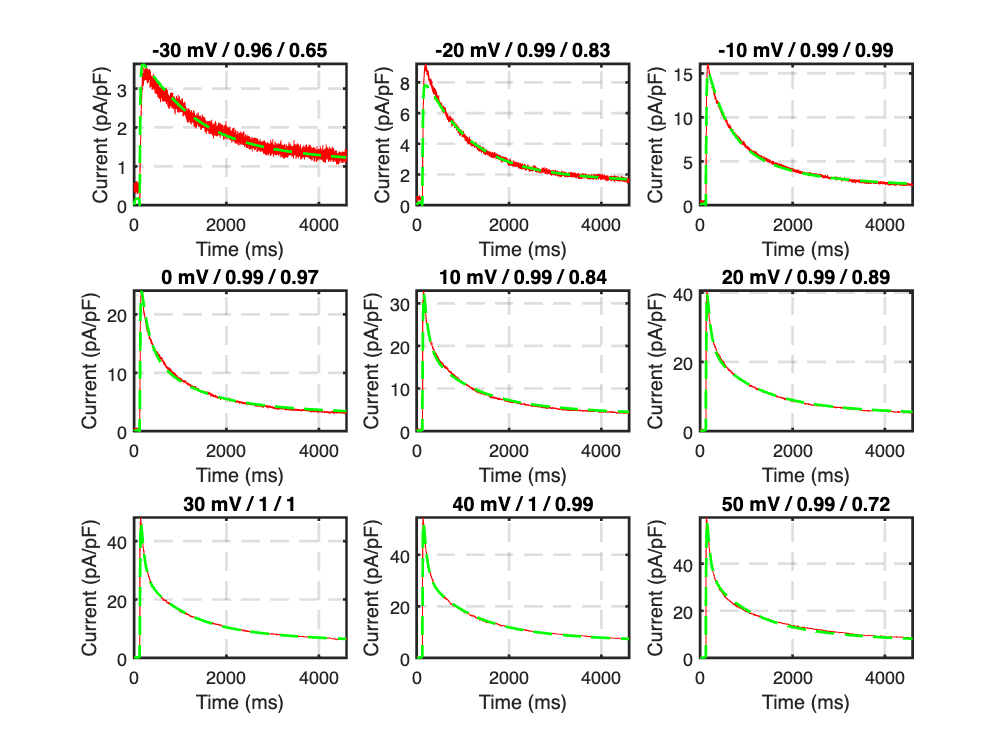

File 8: 15o26031.xlsx / Mean R-squared: 0.950900 / Mean L2: 0.804300 


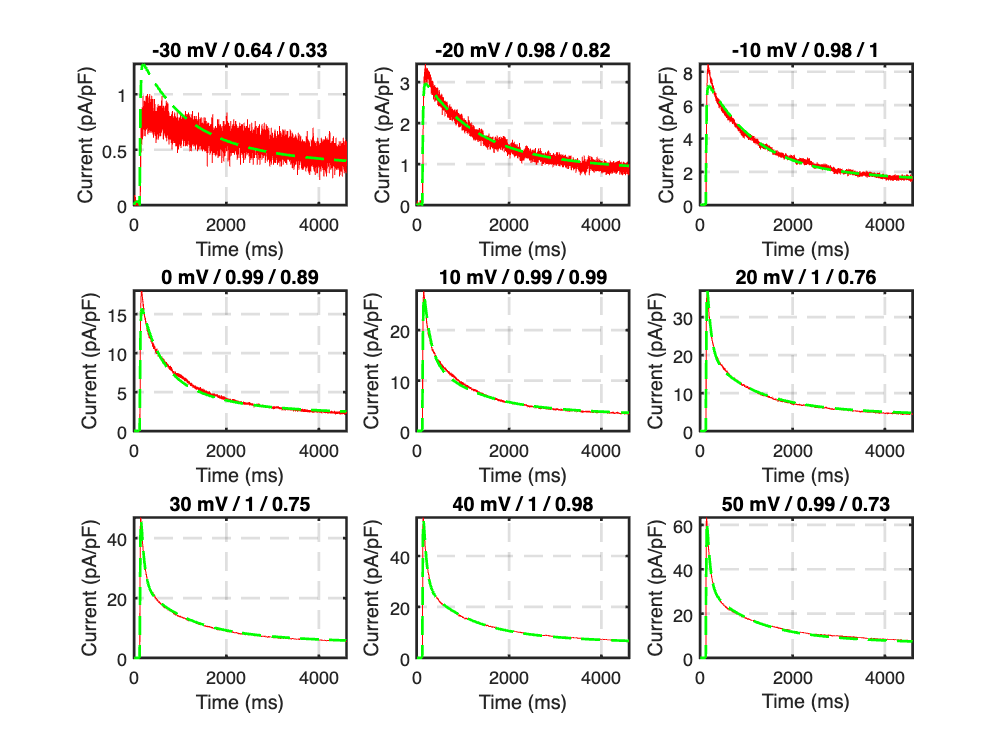

File 9: 15o29002.xlsx / Mean R-squared: 0.976367 / Mean L2: 0.826833 


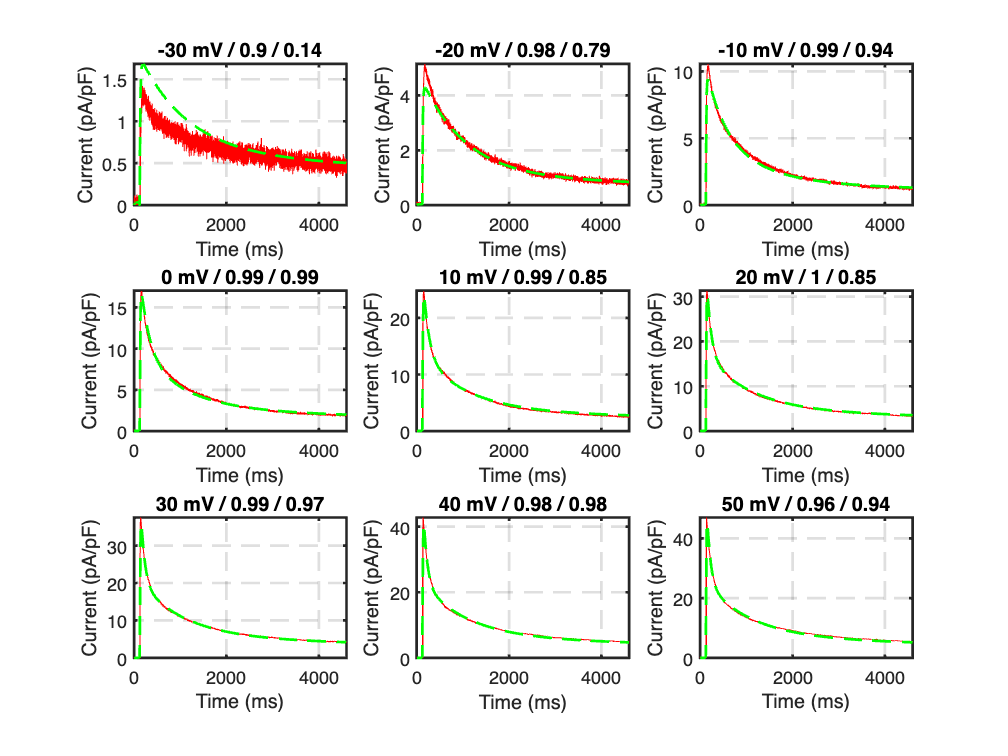

File 10: 15o29009.xlsx / Mean R-squared: 0.958011 / Mean L2: 0.729178 


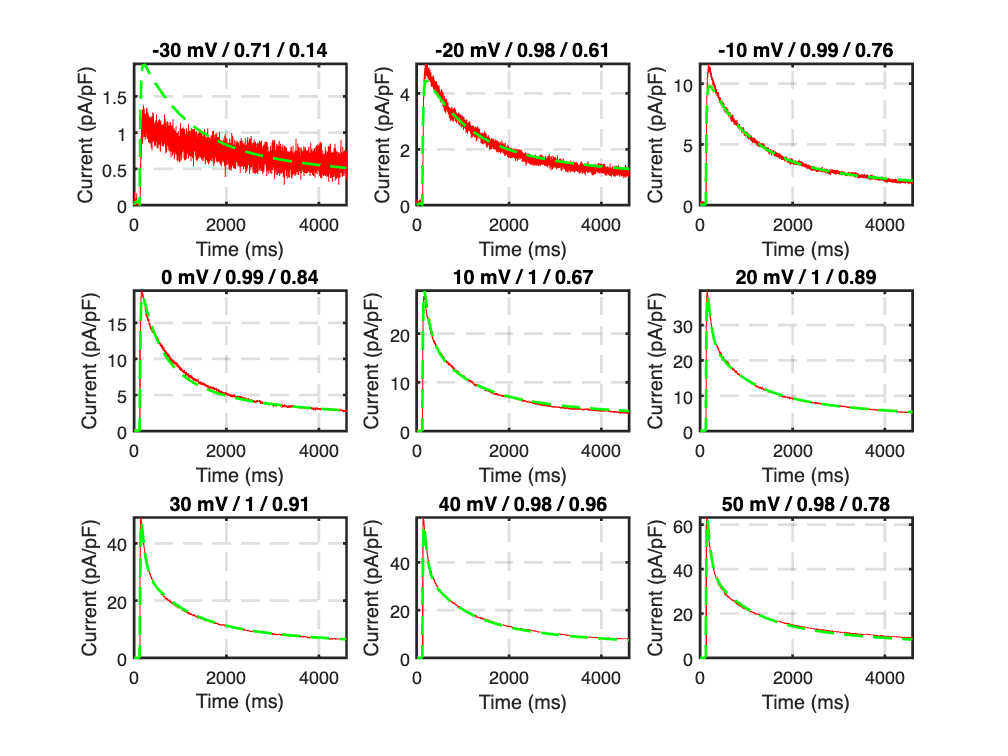

File 11: 15o29012.xlsx / Mean R-squared: 0.987200 / Mean L2: 0.797022 


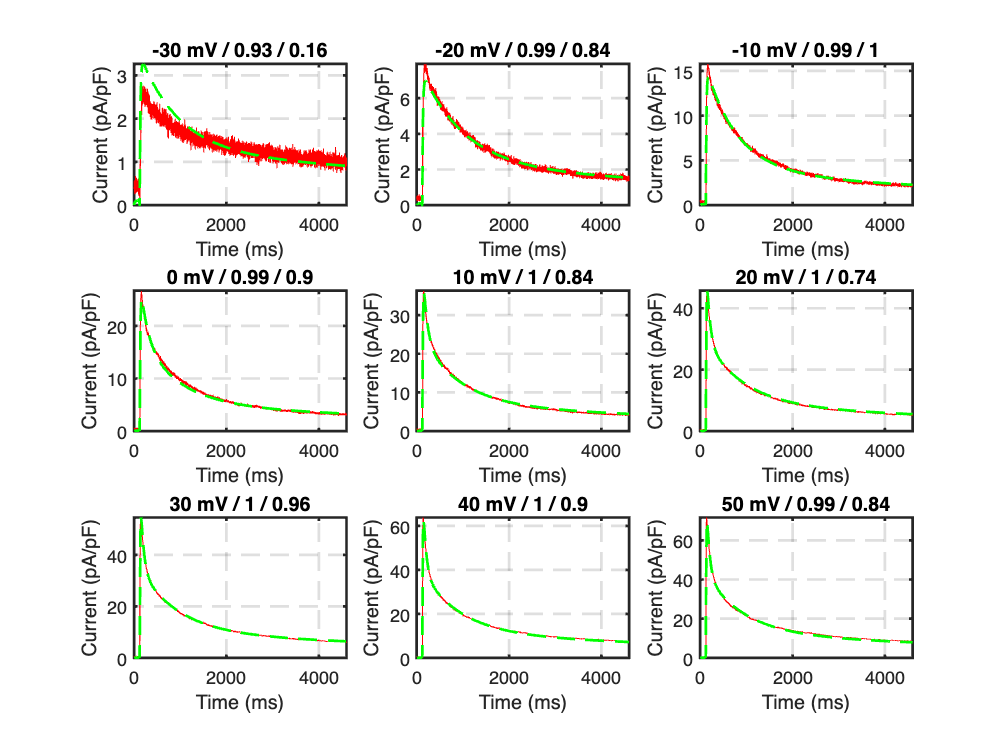

File 12: 15o29015.xlsx / Mean R-squared: 0.955778 / Mean L2: 0.886278 


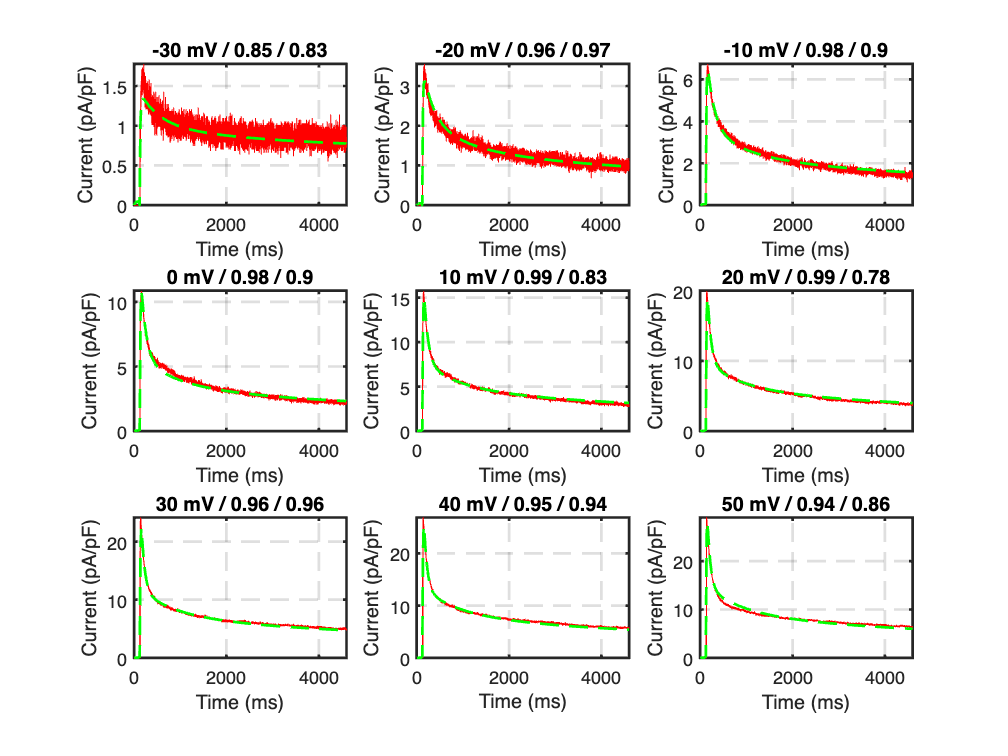

File 13: 15o29021.xlsx / Mean R-squared: 0.984533 / Mean L2: 0.807089 


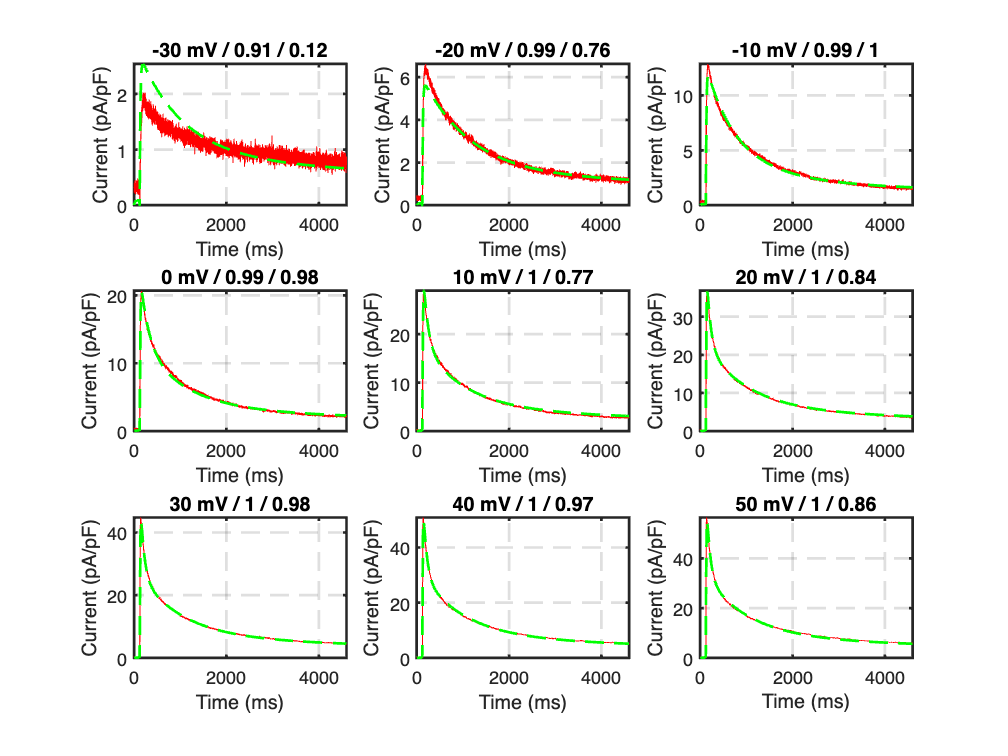

File 14: 15o29024.xlsx / Mean R-squared: 0.976211 / Mean L2: 0.855533 


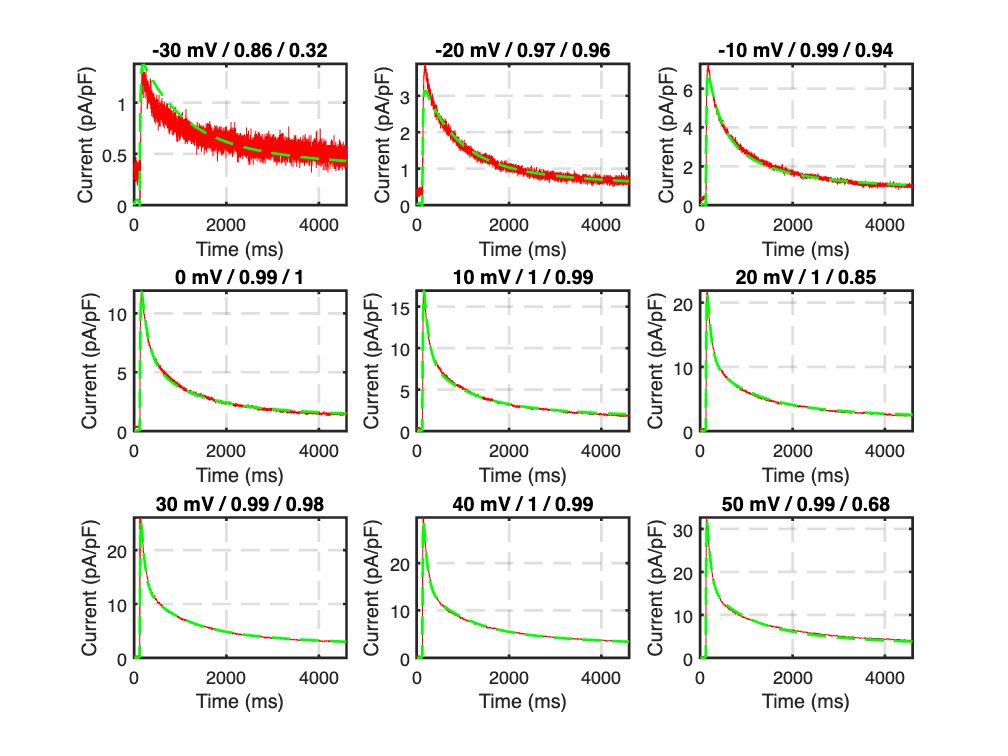

File 15: 15o29027.xlsx / Mean R-squared: 0.976044 / Mean L2: 0.841367 


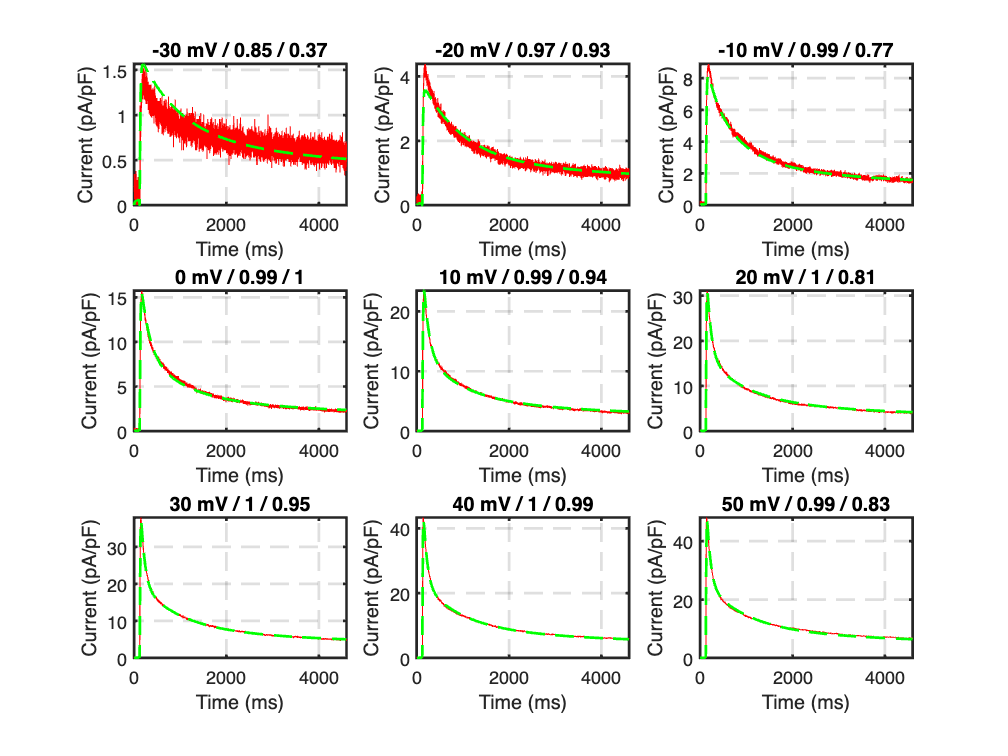

File 16: 15o20002.xlsx / Mean R-squared: 0.984111 / Mean L2: 0.669744 


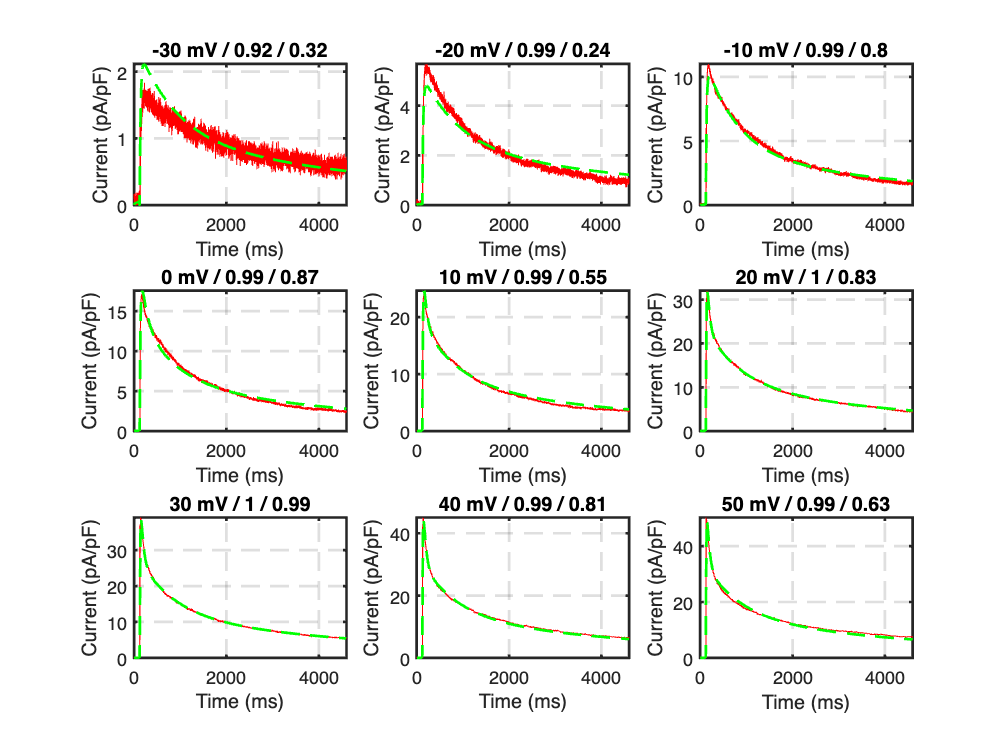

File 17: 15o20005.xlsx / Mean R-squared: 0.974100 / Mean L2: 0.784944 


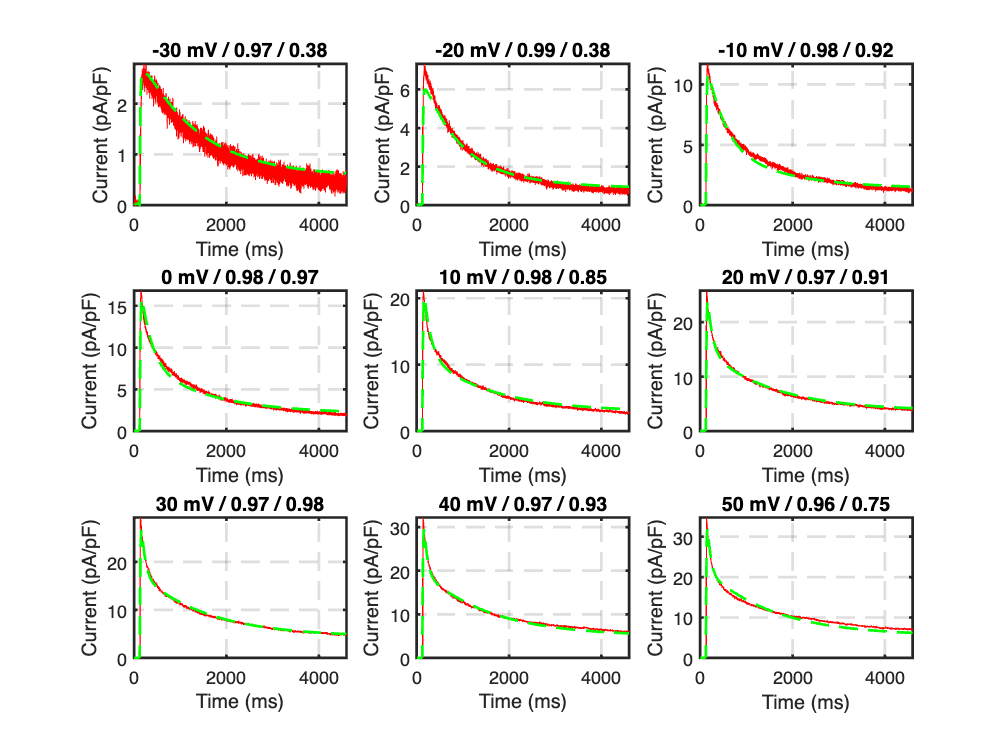

File 18: 15o20010.xlsx / Mean R-squared: 0.921767 / Mean L2: 0.765644 


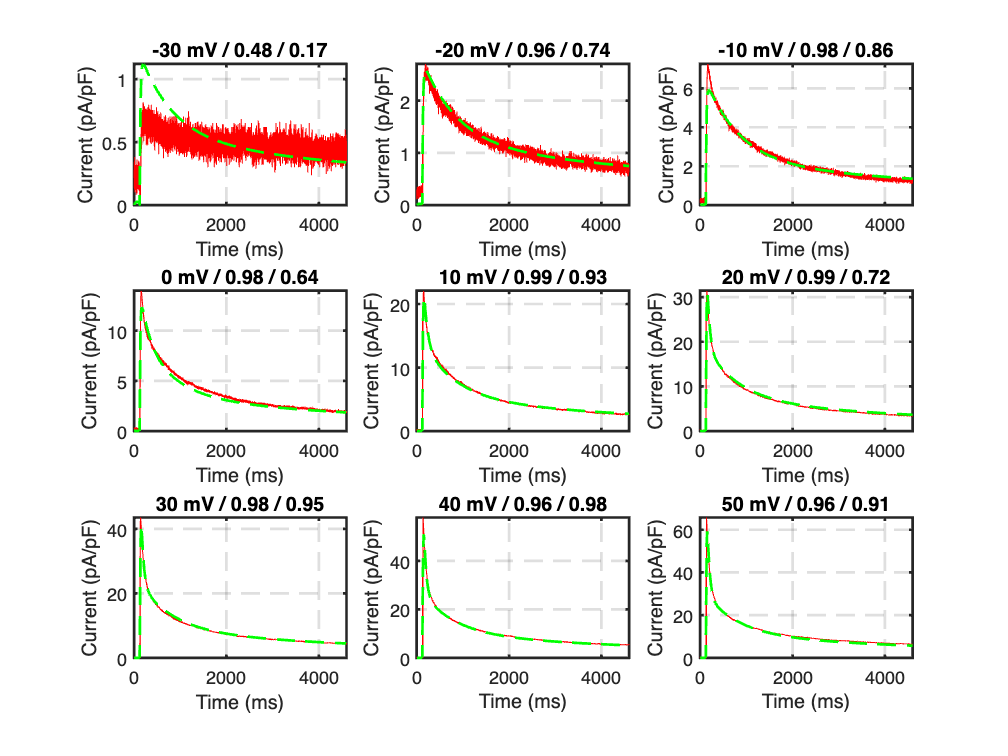

File 19: 15o20015.xlsx / Mean R-squared: 0.971167 / Mean L2: 0.817633 


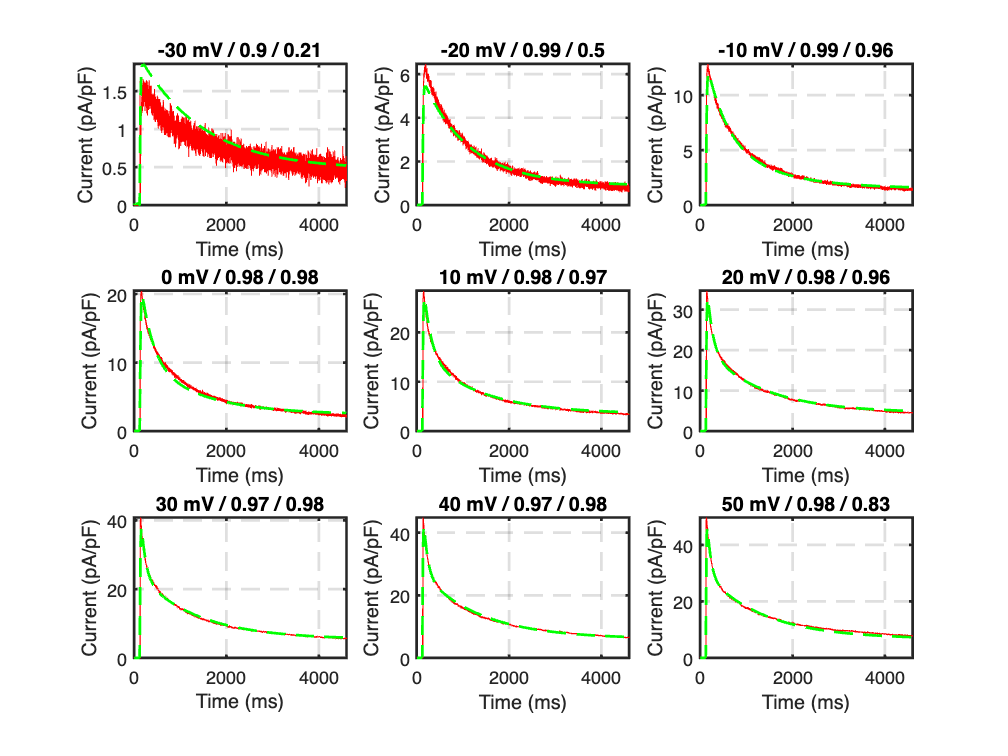

File 20: 15o21003.xlsx / Mean R-squared: 0.980567 / Mean L2: 0.746944 


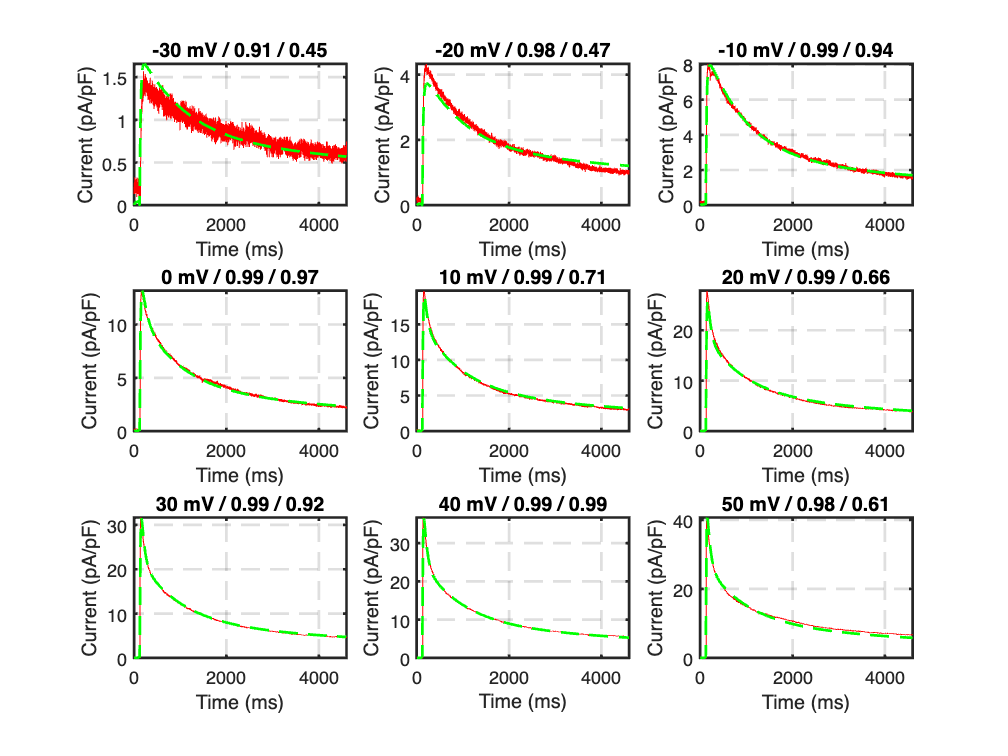

File 21: 15o21008.xlsx / Mean R-squared: 0.971256 / Mean L2: 0.816400 


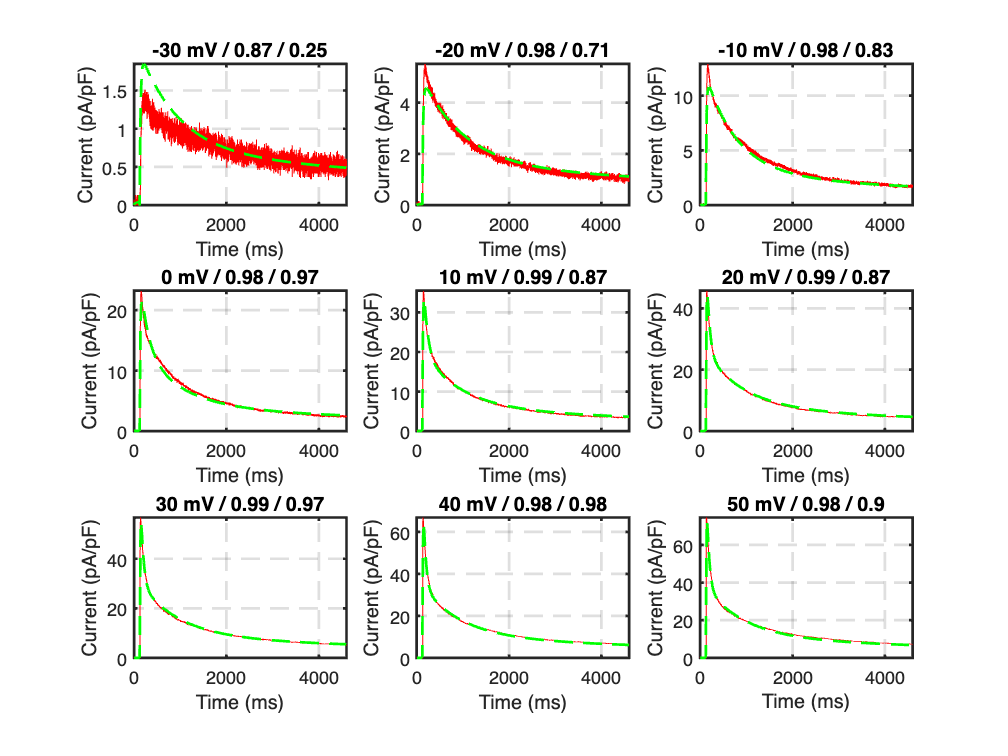

File 22: 15o22002.xlsx / Mean R-squared: 0.947856 / Mean L2: 0.880500 


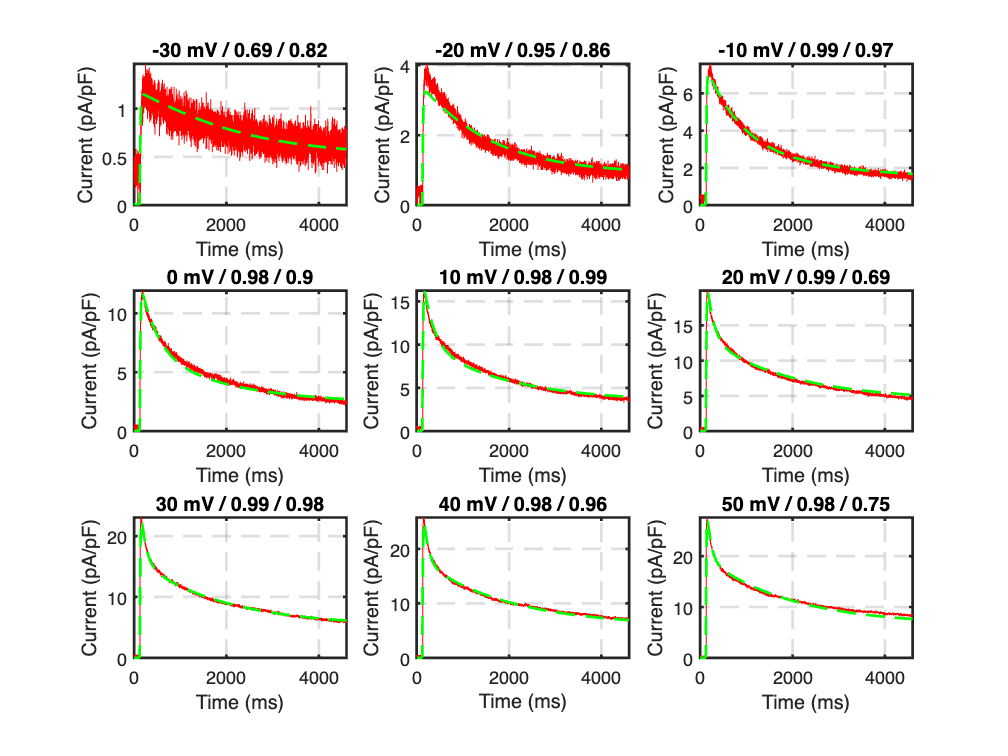

File 23: 15o22008.xlsx / Mean R-squared: 0.851922 / Mean L2: 0.911967 


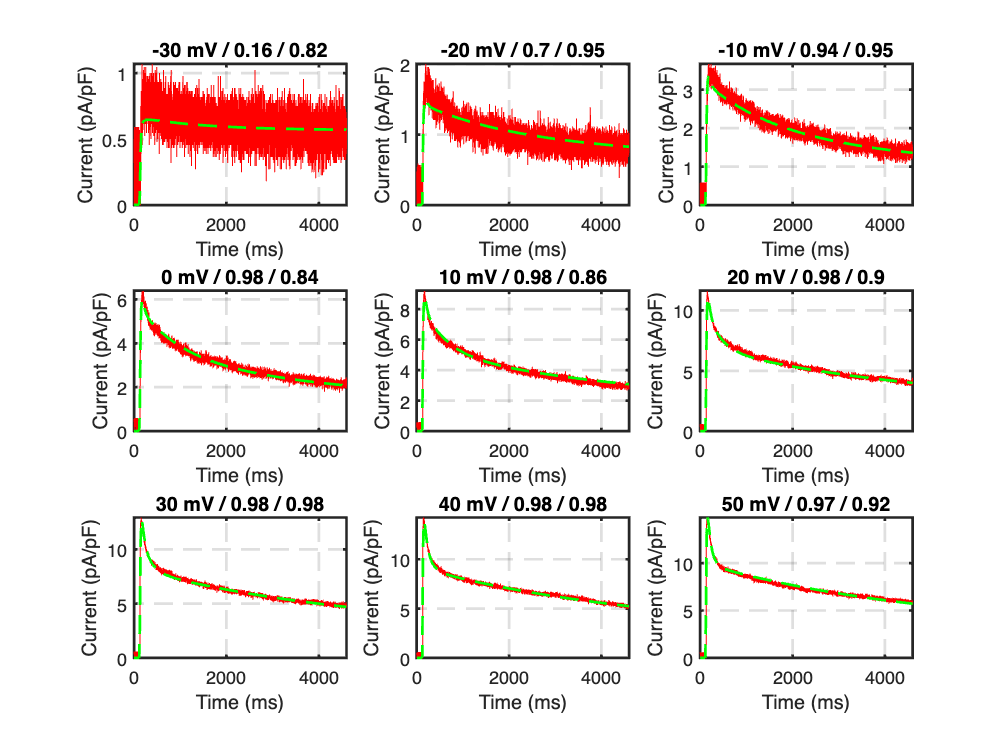

File 24: 15n10002.xlsx / Mean R-squared: 0.964589 / Mean L2: 0.837733 


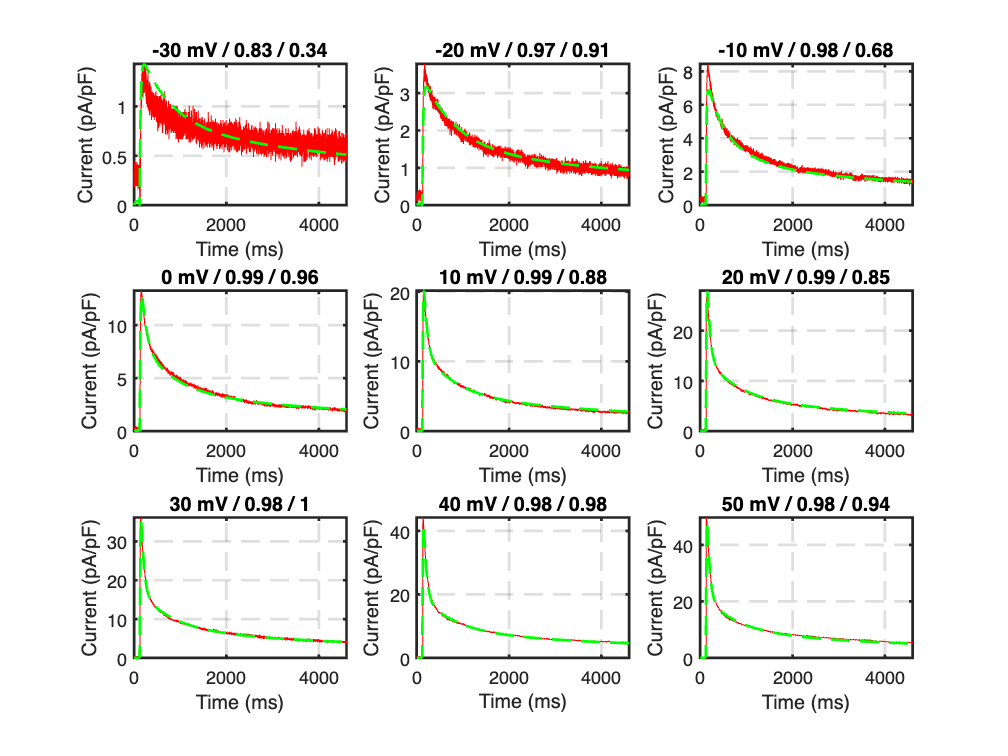

File 25: 15n10006.xlsx / Mean R-squared: 0.977100 / Mean L2: 0.770844 


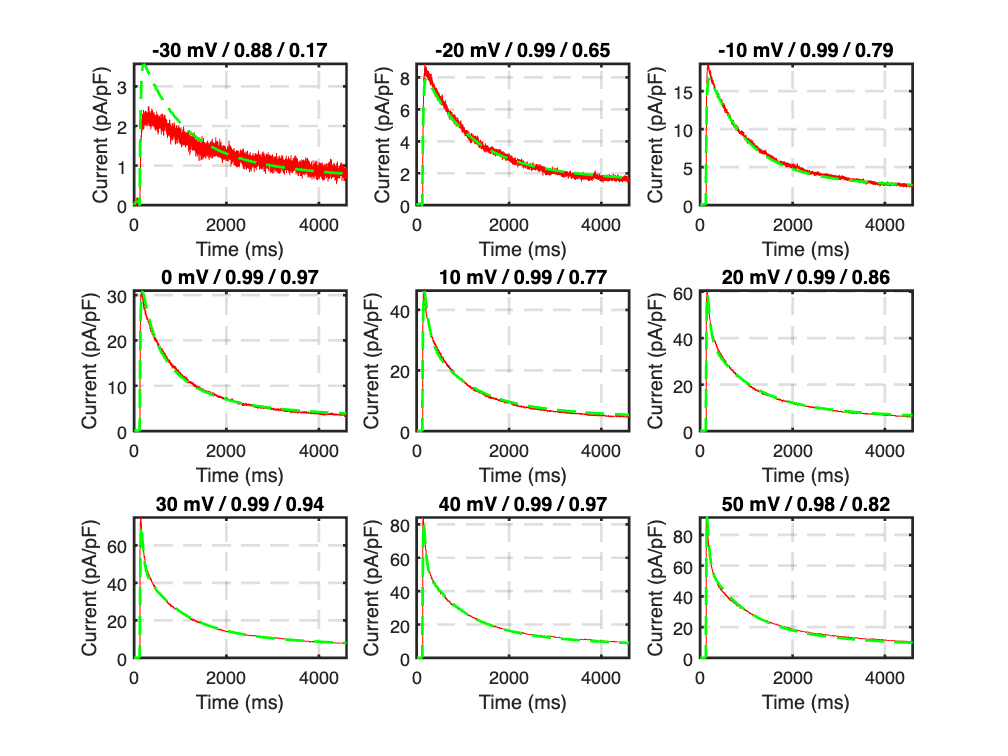

File 26: 15n10009.xlsx / Mean R-squared: 0.976856 / Mean L2: 0.815178 


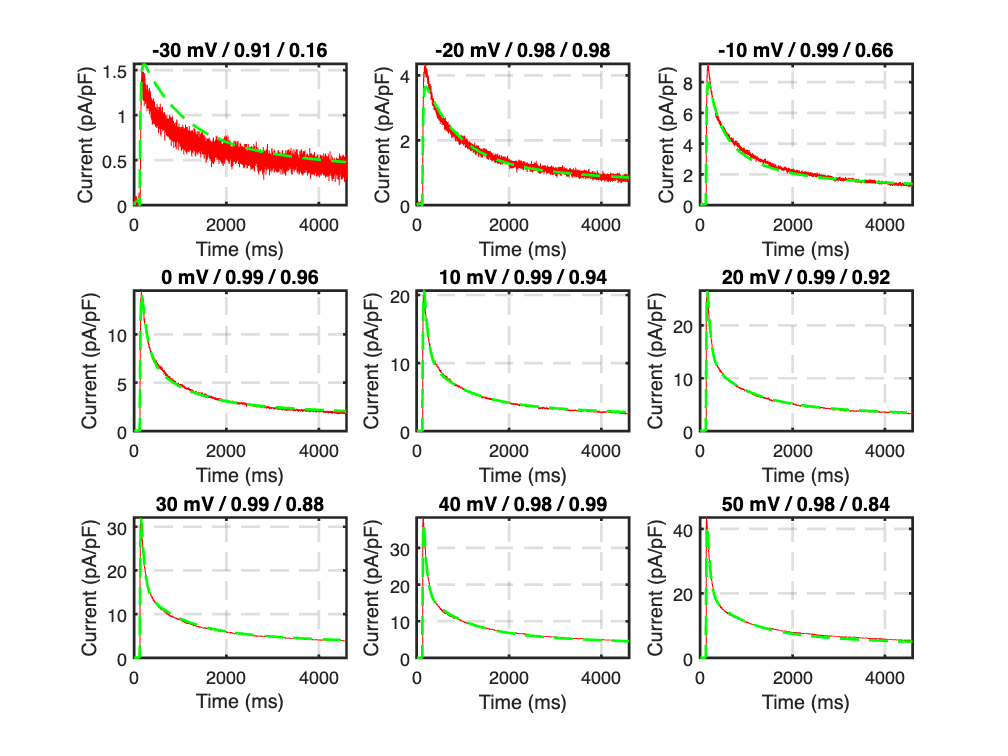

File 27: 15n10012.xlsx / Mean R-squared: 0.953456 / Mean L2: 0.886378 


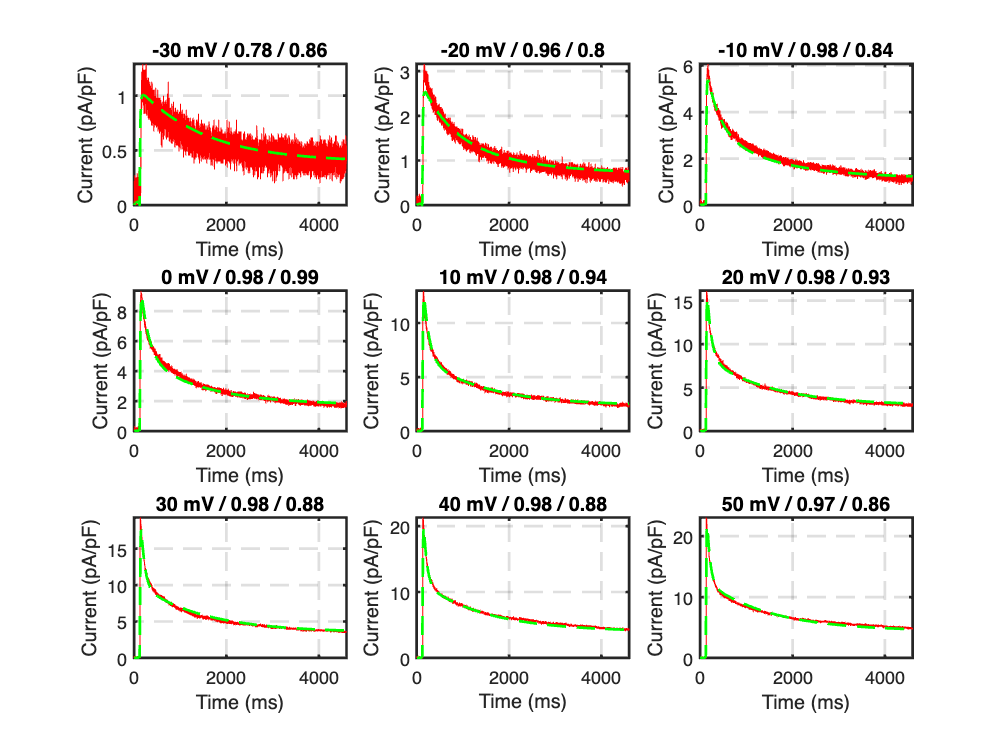

File 28: 15n23002.xlsx / Mean R-squared: 0.966822 / Mean L2: 0.805211 


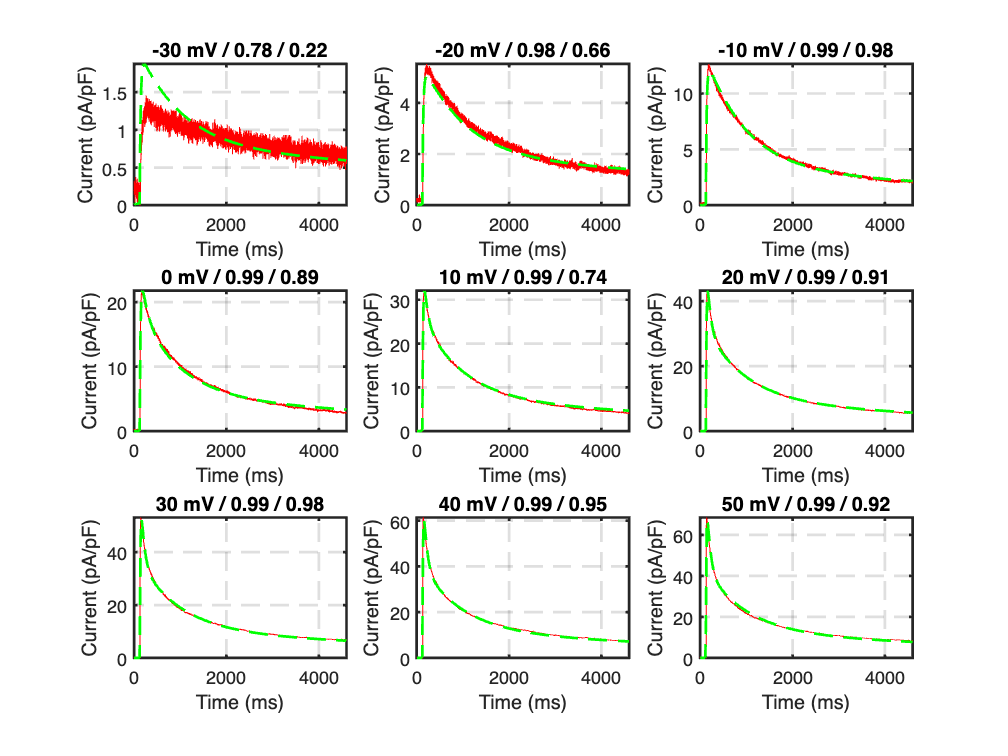

File 29: 15n23005.xlsx / Mean R-squared: 0.978267 / Mean L2: 0.769567 


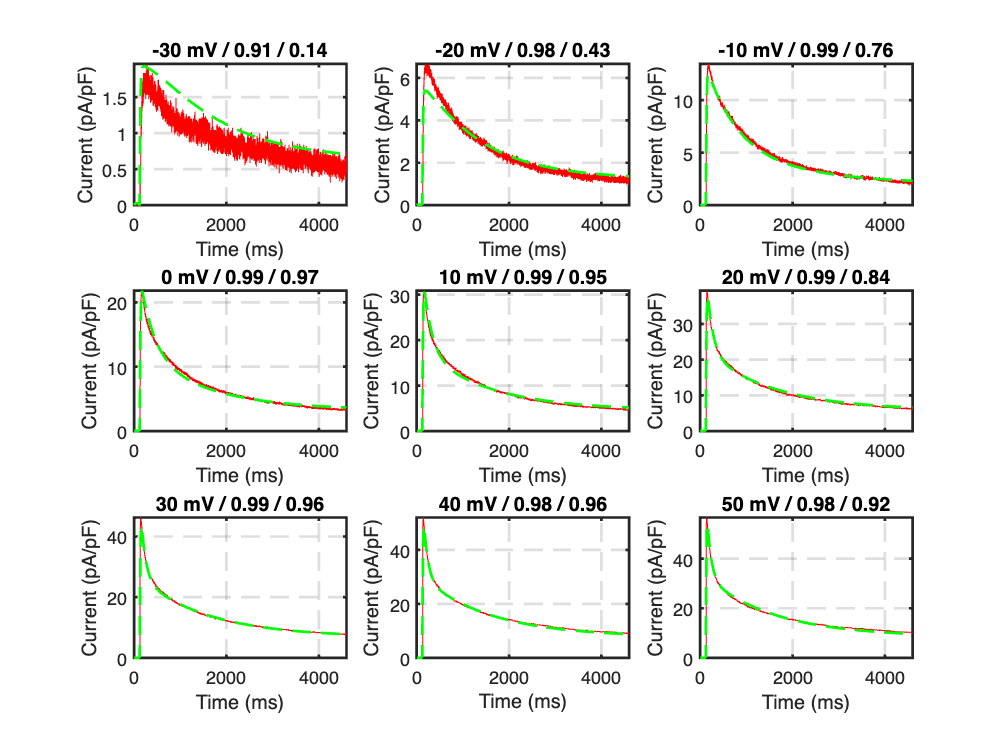

File 30: 15n23008.xlsx / Mean R-squared: 0.954778 / Mean L2: 0.770156 


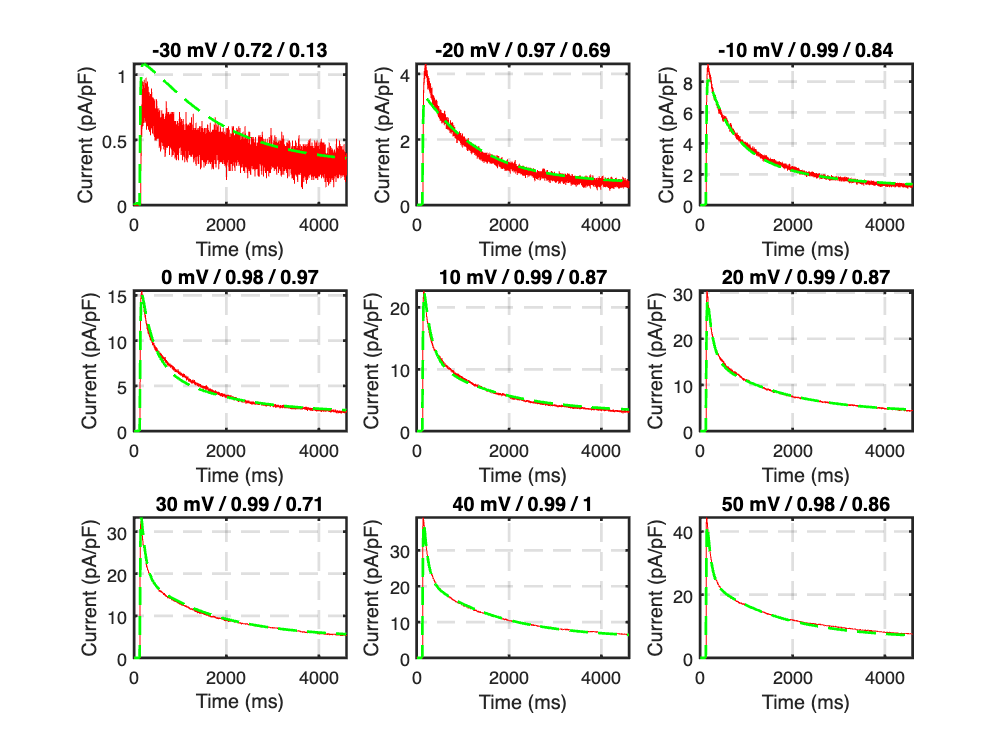

File 31: 15n23011.xlsx / Mean R-squared: 0.984056 / Mean L2: 0.805589 


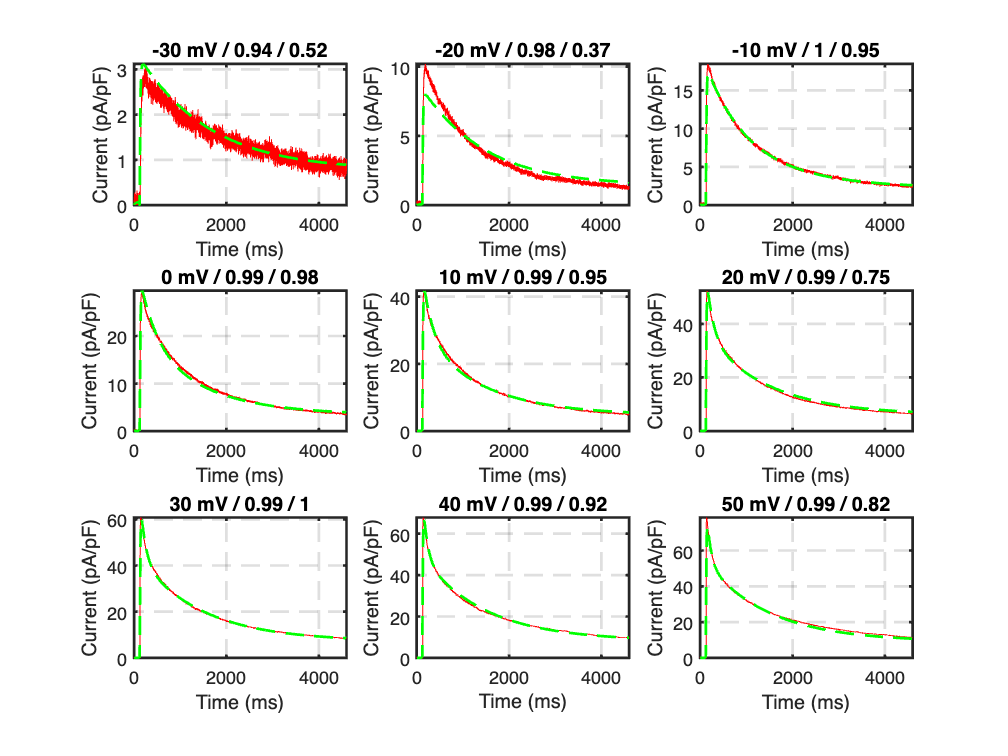

File 32: 15n23014.xlsx / Mean R-squared: 0.979211 / Mean L2: 0.792822 


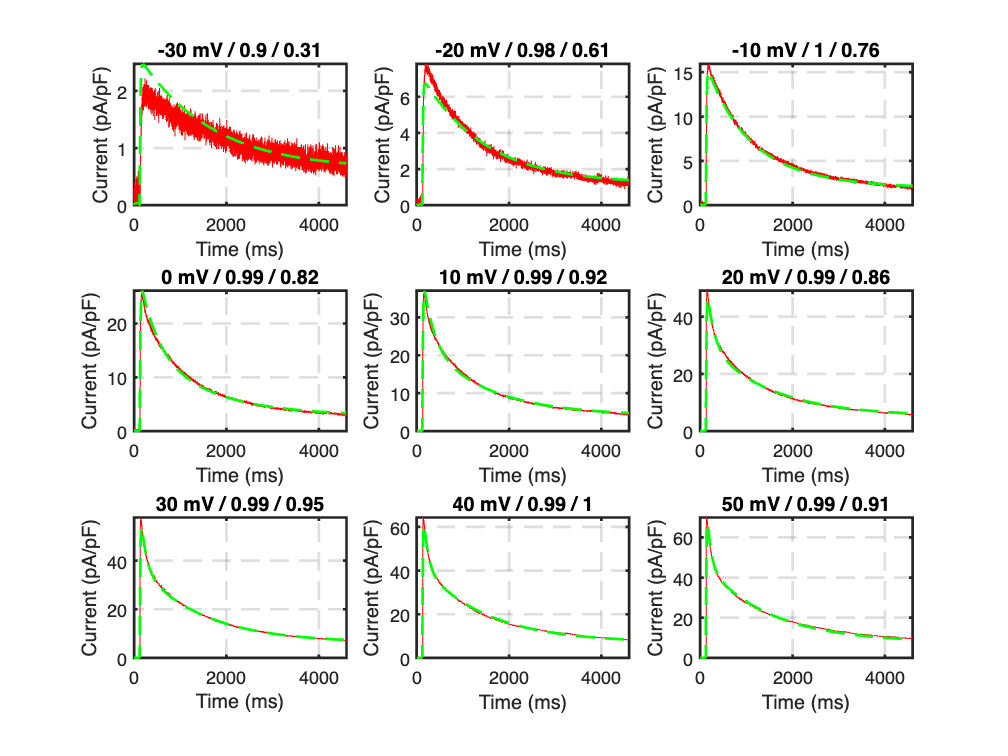

File 33: 15n23019.xlsx / Mean R-squared: 0.968922 / Mean L2: 0.711222 


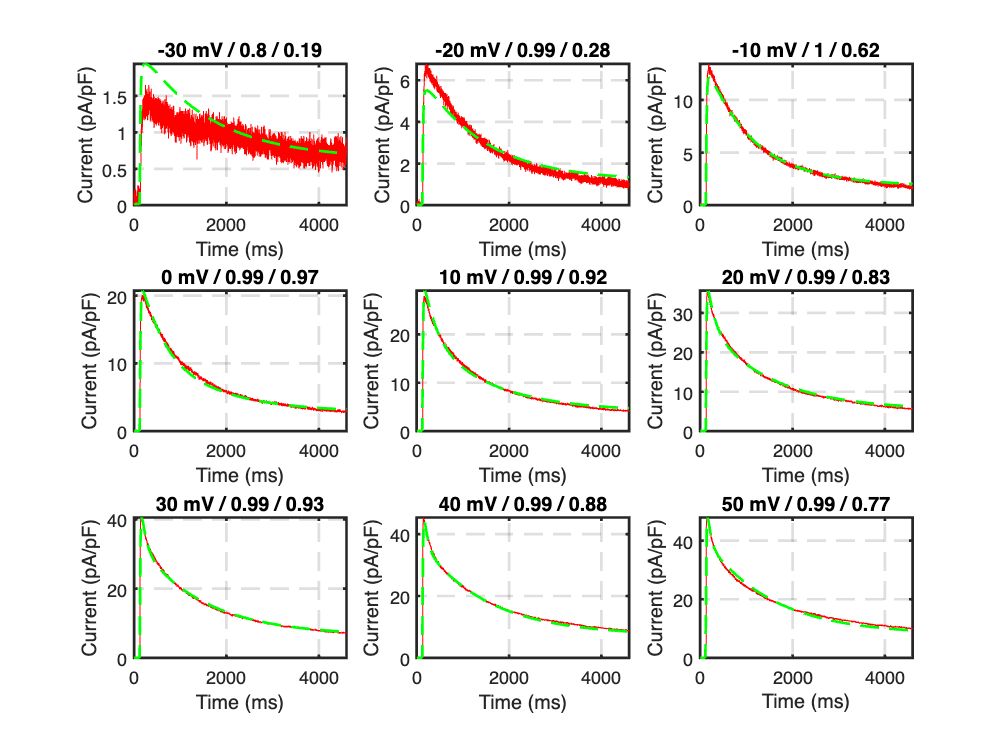

File 34: 15n23022.xlsx / Mean R-squared: 0.970456 / Mean L2: 0.720844 


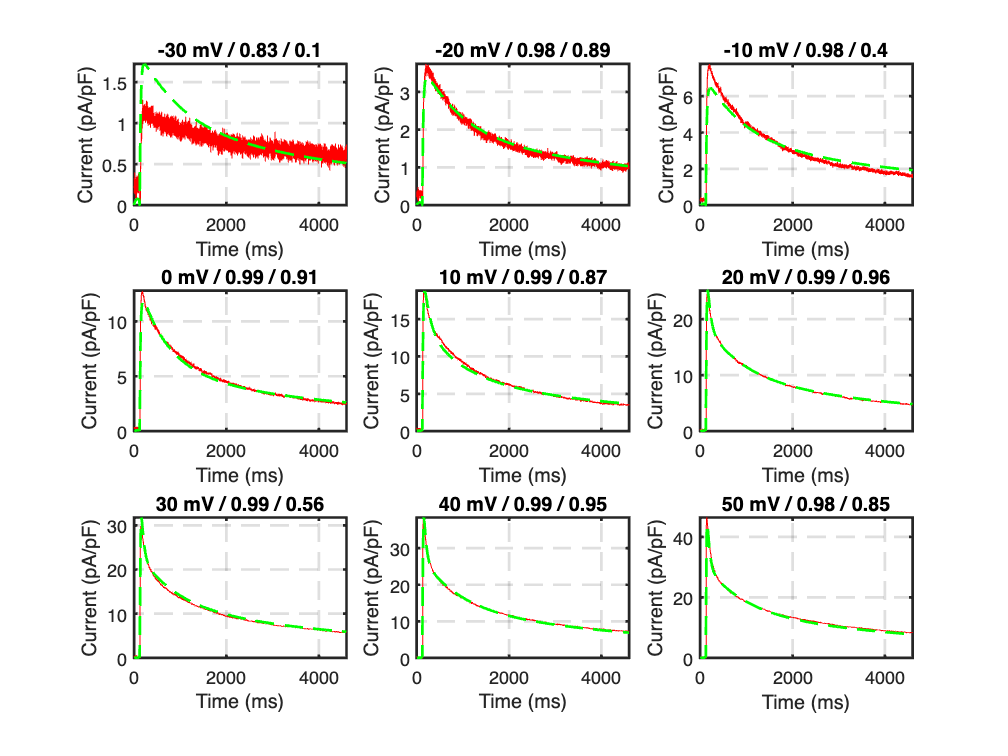

for i=1:num_files
    % calibrated parameters
    calib = table2array(readtable(fullfile(pwd,calib_dir,file_group,file_names(i))));
    sol = gen_sol_vec(calib, mdl_struct, psize);

    % experimental data
    exp_data = table2array(readtable(...
        fullfile(data_dir, strcat(file_group,"-preprocessed"), file_names(i))));
    t = exp_data(:,1);
    yksum = exp_data(:,2:end);

    [~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
    [~, ideal_end_idx] = min(abs(t - ideal_end_time));
    t = t(1:ideal_end_idx);
    yksum = yksum(1:ideal_end_idx, :);

    protocol{4} = t;
    protocol{5} = t(1:ideal_hold_idx);
    pulse_t = t(ideal_hold_idx+1:end);
    pulse_t_adj = pulse_t - pulse_t(1);
    protocol{6} = pulse_t_adj;
    
    % R2 & L2 measures
    fname = file_names(i);
    r2l2_row = r2l2(r2l2.file_name == fname,:);
    r2 = r2l2_row{1,1+2*length(volts)+1};
    l2 = r2l2_row{1,1+2*length(volts)+2};
    fprintf("File %i: %s / Mean R-squared: %f / Mean L2: %f \n",...
        i,fname,r2,l2)

    figure('Color','w')
    for j=1:length(volts)
        yksum_i = yksum(:,j);
        ymx = kcurrent_basic(sol, mdl_struct, pdefault, protocol, volts(j));
        yksum_hat1 = sum(ymx,2);

        r2 = r2l2_row{1, i1 + (j-1)*2};
        l2 = r2l2_row{1, i2 + (j-1)*2};

        subplot(3,3,j)
        plot(t, yksum_i, 'Color','red')
        hold on
        plot(t, yksum_hat1, '--', 'Color','green', 'LineWidth',1.5)
        hold off
        axis tight
        grid on
        title(strcat(...
            string(volts(j))," mV /"," ",num2str(round(r2,2))," / ",num2str(round(l2,2))));
        xlabel('Time (ms)');
        ylabel('Current (pA/pF)');
        get(gcf,'CurrentAxes');
        set(gca,'YDir','normal');
        set(gca,'LineWidth',1.5);
        set(gca,'GridLineStyle','--')
    end
end

function [mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end